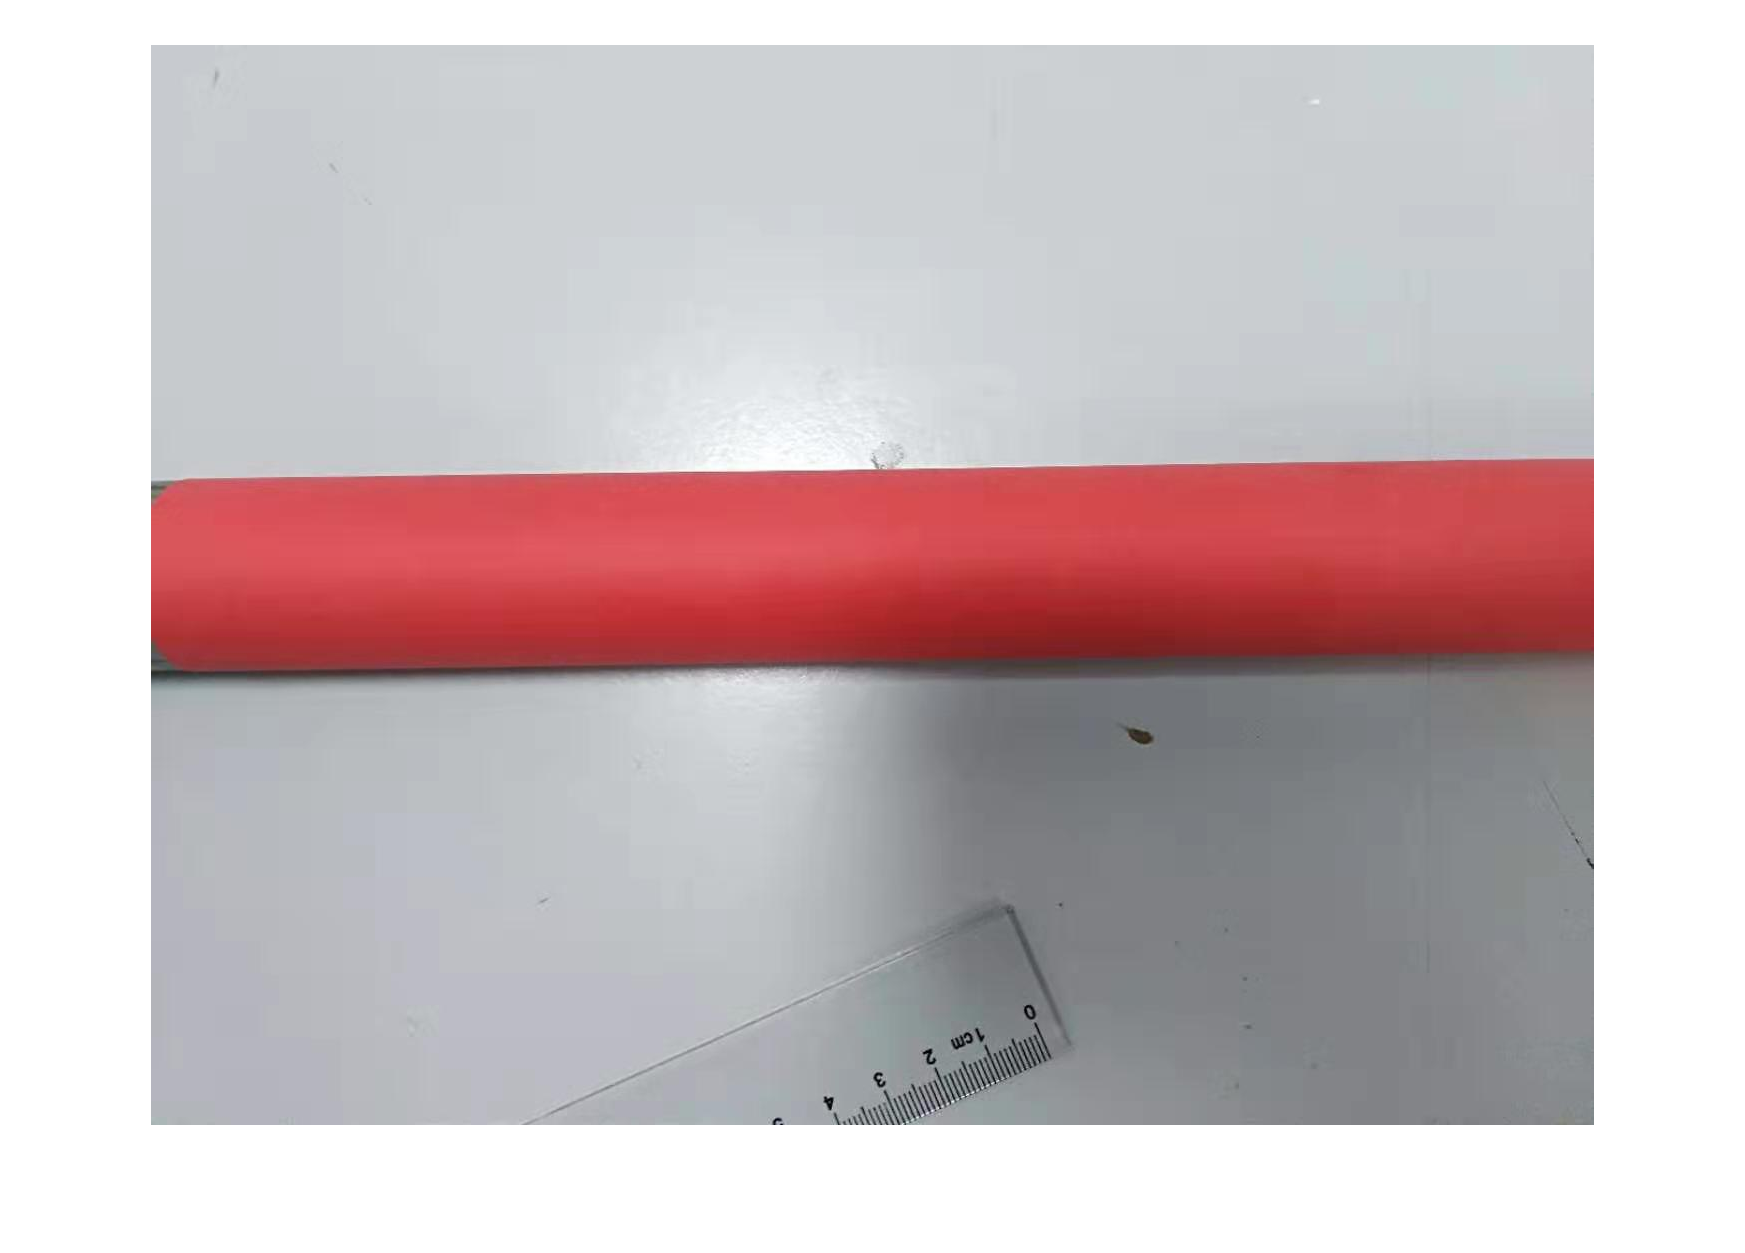

img = imread("./data/1.jpg");
img = im2double(img);

figure, imshow(img);

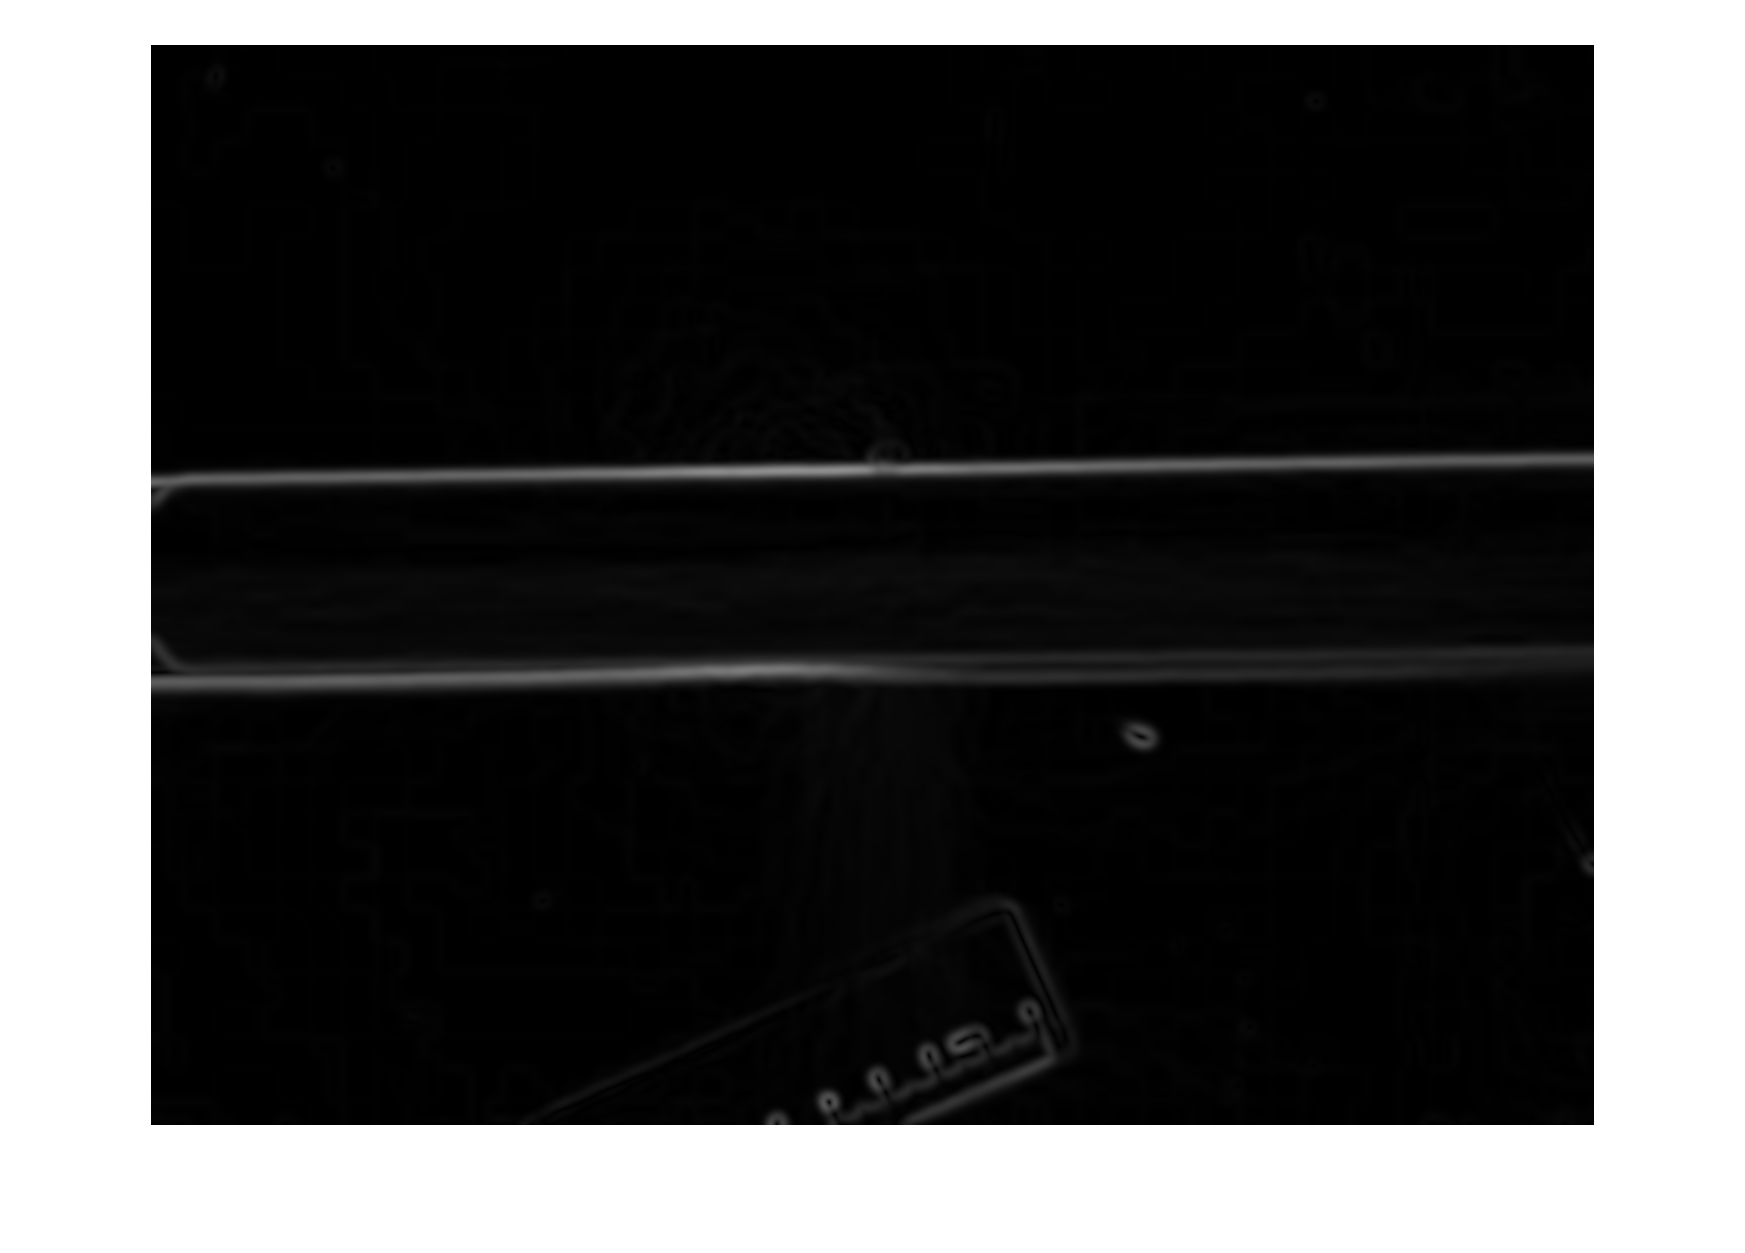

edges = compute_edges(img,5);

figure, imshow(edges);

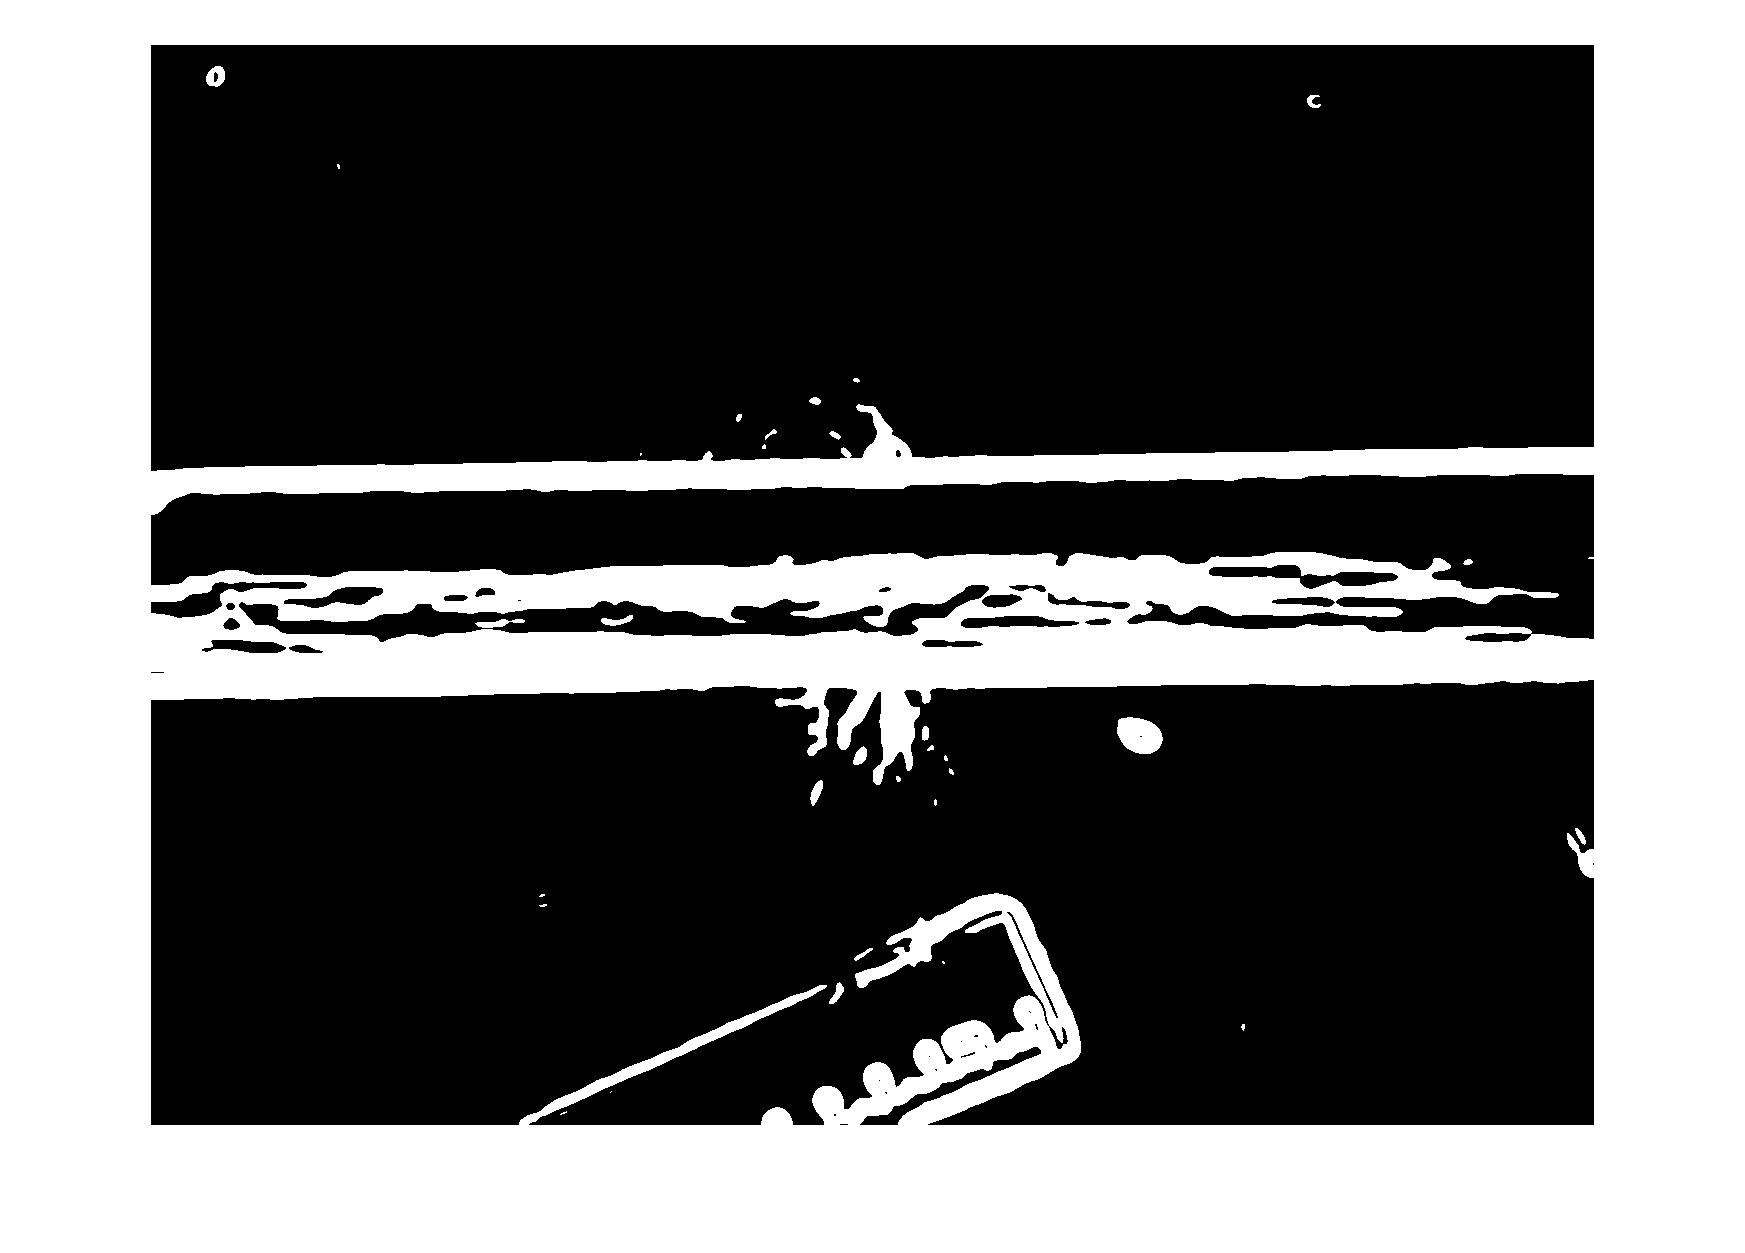

edges_bin = edges > 0.03;

figure, imshow(edges_bin);

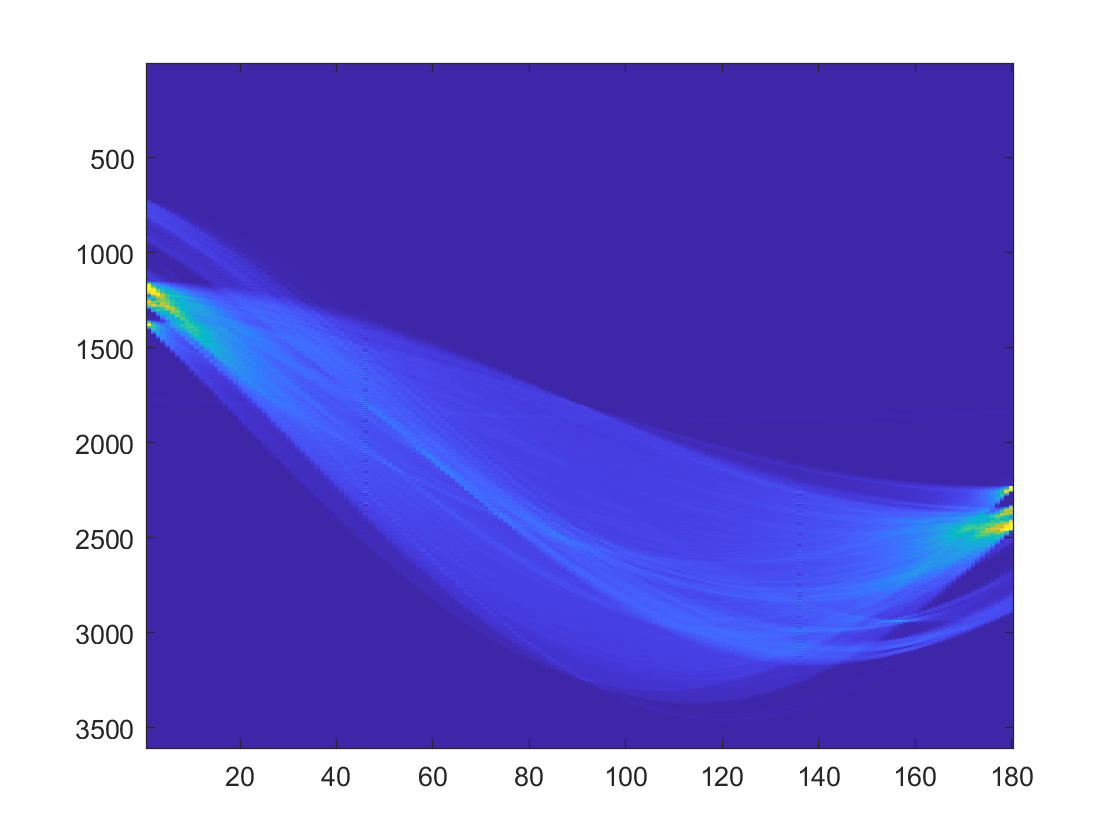

[h, thetas, rhos] = hough(edges_bin);

figure, imagesc(h);

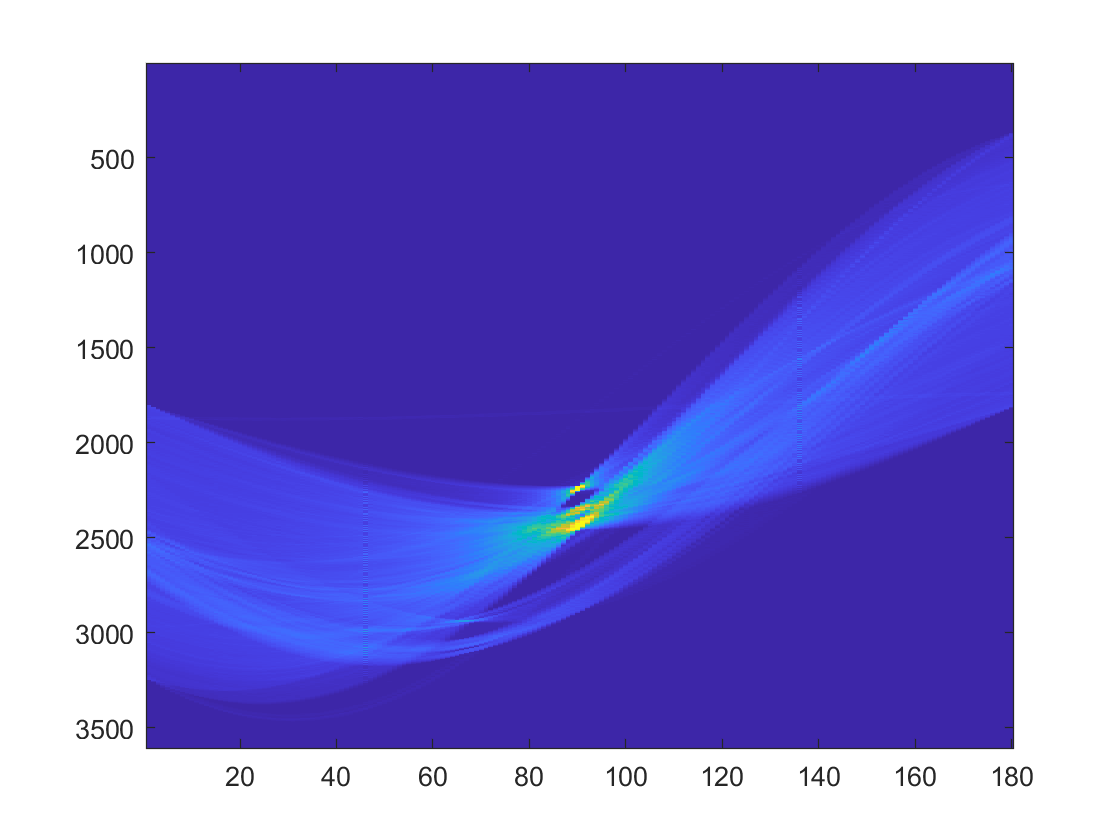

peaks = houghpeaks(h,2);
rho1=rhos(peaks(1,1));
theta1=thetas(peaks(1,2))/180*pi;

if theta1 < -pi/4 || pi/4 < theta1
    split = size(h,2)/2;
    h_left = flip(h(:,1:split),1);
    h_right = h(:,split+1:end);
    h = [h_right h_left];
    figure, imagesc(h);
    thetas = [thetas(split+1:end) thetas(1:split)];
    
    peaks = houghpeaks(h,2);
    rho1=rhos(peaks(1,1));
    theta1=thetas(peaks(1,2))/180*pi;
end


rho2=rhos(peaks(2,1));
theta2=thetas(peaks(2,2))/180*pi;

rho1

rho1 = 654

theta1

theta1 = 1.5359

rho2

rho2 = 429

theta2

theta2 = 1.5533